# Experiment 3: Frequency Modulation

By Yusuf Ahmed Khan, Serial Number: 12

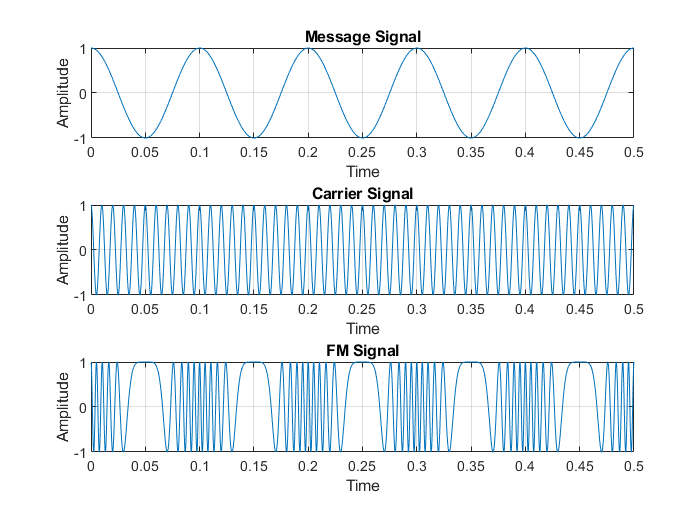

fm=10; % frequeny of message signal
fc=100; % frequency of carrier
B=10; % mod index of FM, kf* Am / fm
t=0:0.0001:0.5; 
m=cos(2*pi*fm*t); %message signal
subplot(3,1,1);
plot(t,m)
xlabel('Time');
ylabel('Amplitude');
title('Message Signal');
grid on;
 
c=cos(2*pi*fc*t);
subplot(3,1,2);
plot(t,c)
xlabel('Time');
ylabel('Amplitude');
title('Carrier Signal');
grid on;

y=cos(2*pi*fc*t+(B*sin(2*pi*fm*t))); %FM signal
subplot(3,1,3)
plot(t,y);
xlabel('Time');
ylabel('Amplitude');
title('FM Signal');
grid on;

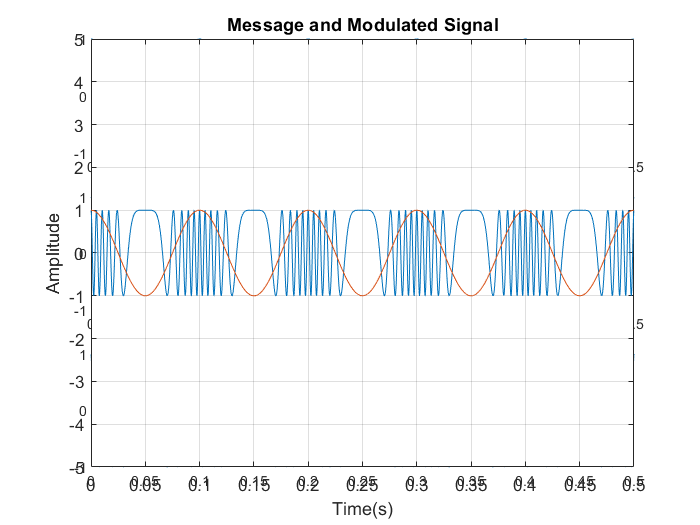

axes
plot(t,y, 'DisplayName','FM Signal');
grid on
hold on
plot(t,m, 'DisplayName','Message Signal')
ylim([-5 5])
xlabel ('Time(s)');
ylabel ('Amplitude');
title('Message and Modulated Signal')